# MEMS 1045 Homework 4: Fundamentals of Feedback and Accuracy

### Problem 1

#### (a)

% plot original data
load systemID_step_data.mat
sz = 5;
figure(1)
scatter(t,y,sz,'filled')
title('Step Response w/ Measurement Noise')
xlabel('Time (s)')
ylabel('Position (um)')

% calculate A
Yss = 1; % um
U = 1; % V
A = Yss/U % um/V

A = 1

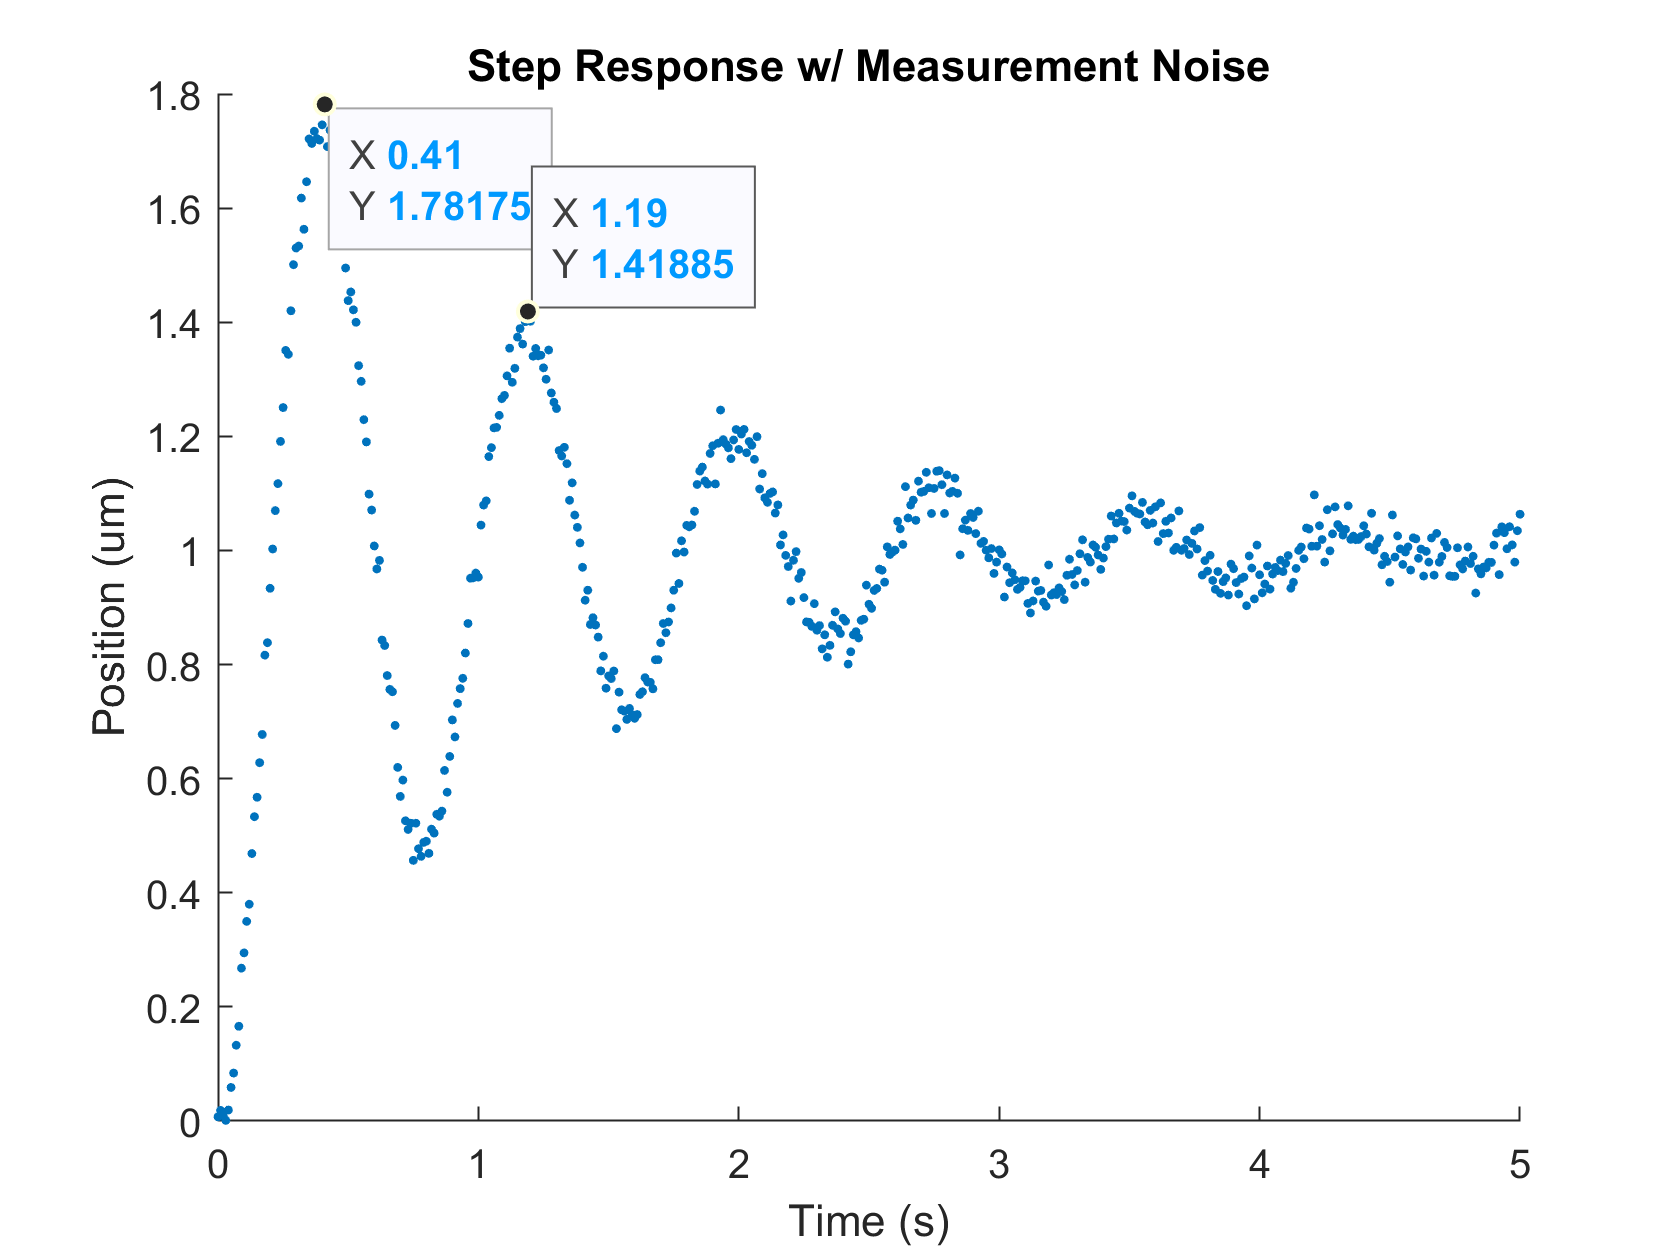


% estimate damped period
ax = gca;
chart = ax.Children(1);
datatip(chart,0.5,1.8);
datatip(chart,1.3,1.45);


T_d = 1.19-0.41; % s

% calculate damped natural frequency
w_d = (2*pi)/T_d;
fprintf('The damped natural frequency of the system is %.2f rad/s.',w_d)

The damped natural frequency of the system is 8.06 rad/s.


% calculate damping ratio using log dec method
x1 = 1.78-Yss;
x2 = 1.42-Yss;
delta = log(x1/x2);

z = sqrt((delta^2)/(4*pi^2+delta^2));
fprintf('The damping ratio of the system is %.2f.',z)

The damping ratio of the system is 0.10.

#### (b)

% find transfer function of system
w_n = w_d/sqrt(1-z^2);
s = tf('s');
G = A*(w_n^2/(s^2+(2*z*w_n*s)+w_n^2))

G =
 
          65.52
  ---------------------
  s^2 + 1.587 s + 65.52
 
Continuous-time transfer function.



#### (c)

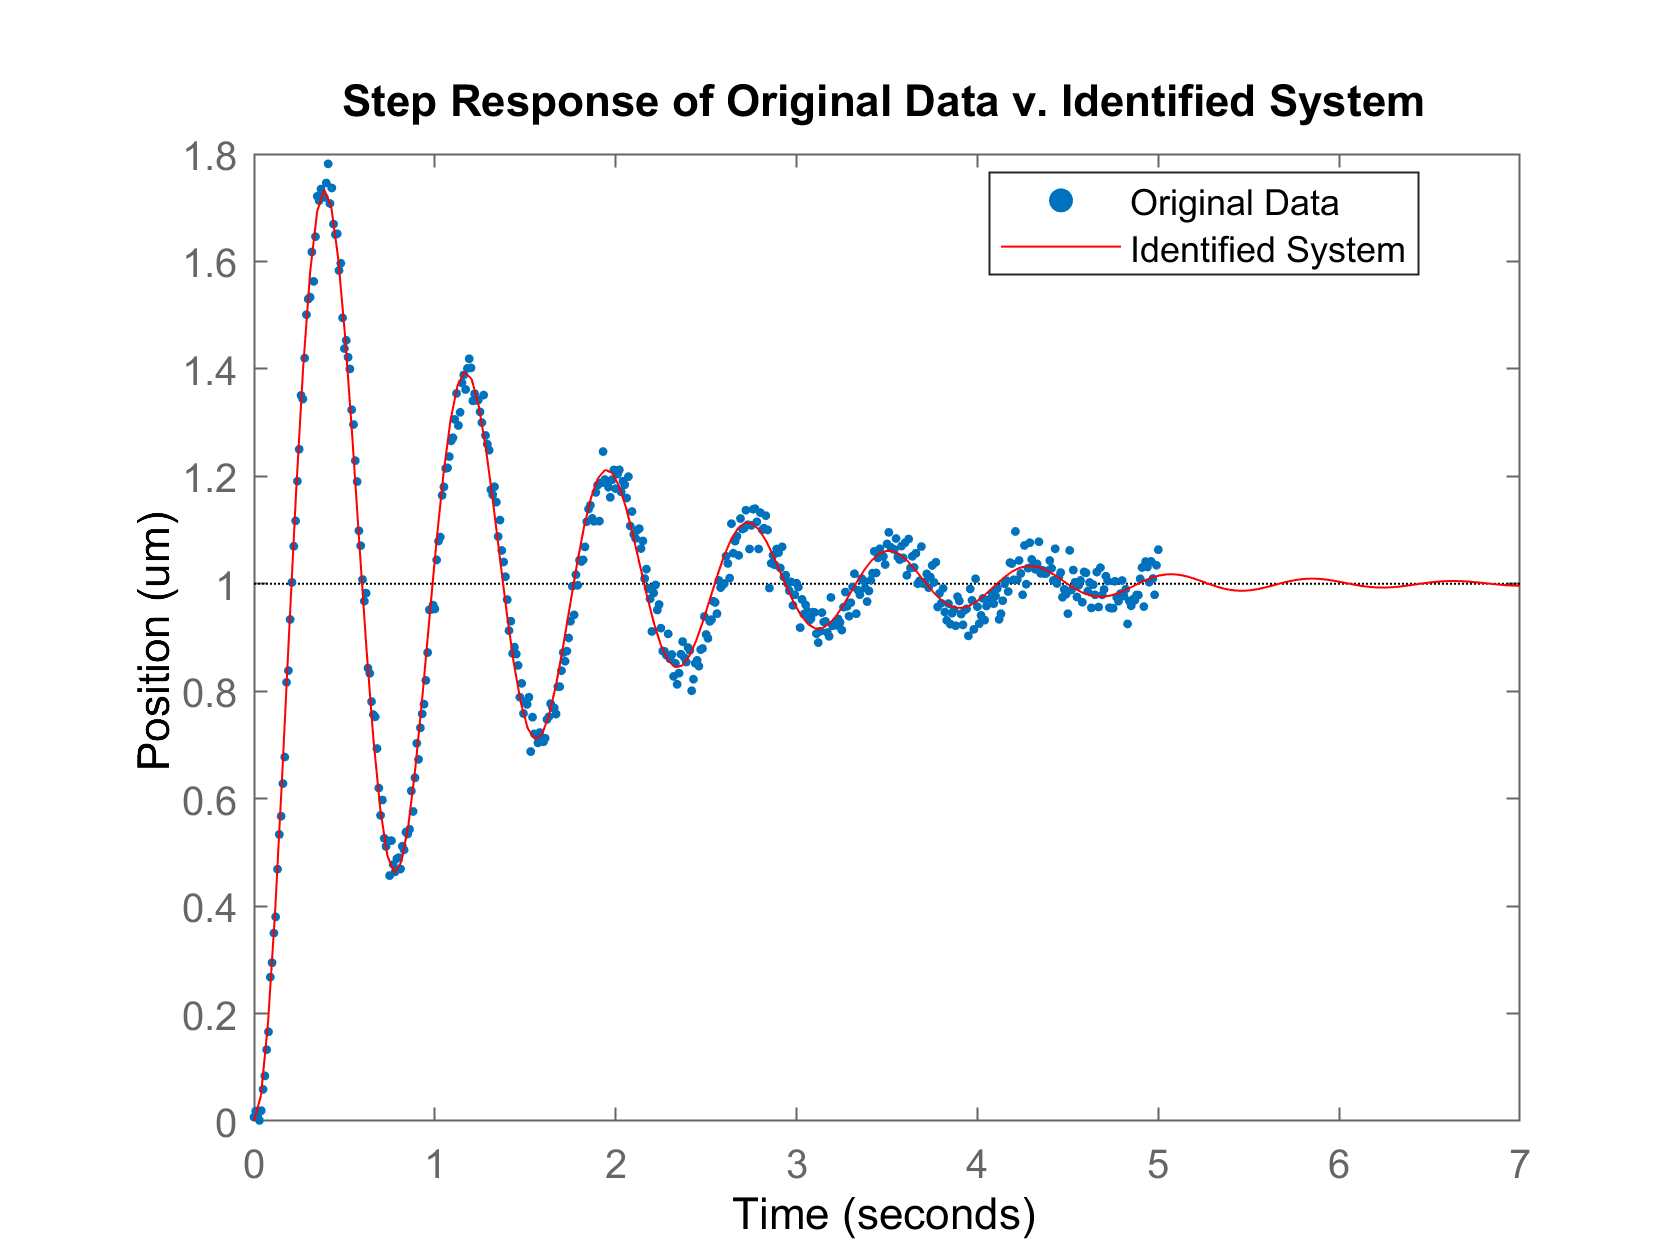

figure(2)
scatter(t,y,sz,'filled')
hold on
step(G,'r')
title('Step Response of Original Data v. Identified System')
xlabel('Time')
ylabel('Position (um)')
legend('Original Data','Identified System','location','best')
hold off

### Problem 2

#### (a)

From input/output table for unity feedback system:


$$\frac{y(s)}{r(s)}=\frac{GK}{1+GK}$$


#### (b)

From input/output table for unity feedback system:


$$\frac{y(s)}{d(s)}=\frac{G}{1+GK}$$


#### (c)

From input/output table for unity feedback system:    


$$\frac{e(s)}{r(s)}=\frac{1}{1+GK}$$



$$\frac{e(s)}{d(s)}=\frac{-G}{1+GK}$$



$$\frac{e(s)}{n(s)}=\frac{-1}{1+GK}$$


### Problem 3

r =   -8.4599 + 0.0000i
  -0.1450 + 1.8775i
  -0.1450 - 1.8775i
